# Actividad 1.3: Parametrización de trayectorias

Víctor Manuel Vázquez Morales A01736352

#### 1. Implementar el código requerido para generar la parametrización de las siguientes trayectorias en un plano 2D: 

**Figura 1: **

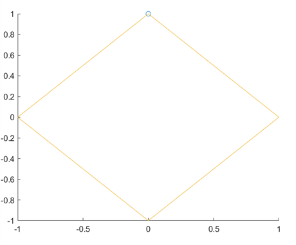

Para replicar la trayectoria mostrada anteriormente debemos antes tener en claro que, en esencia, esta trayectoria sigue la forma de un circulo, es decir, se trata de un coseno para la función de *x *y de seno para la función *y. *Sin embargo, para esta trayectoria, las funciones seno y coseno estan evaludas en puntos especificos, lo que provoca el efecto de esta especie de rombo o cuadrado rotado. Para lograr esto, debemos generar un arreglo de tiempo que aumente pi/2 (90°) entre cada uno de sus valores. Jugando un poco con el vector de tiempo y con su respectiva normalización, asi como su delta de tiempo, se logró encontrar una de muchas opciones que permiten generar esta trayectoria: 

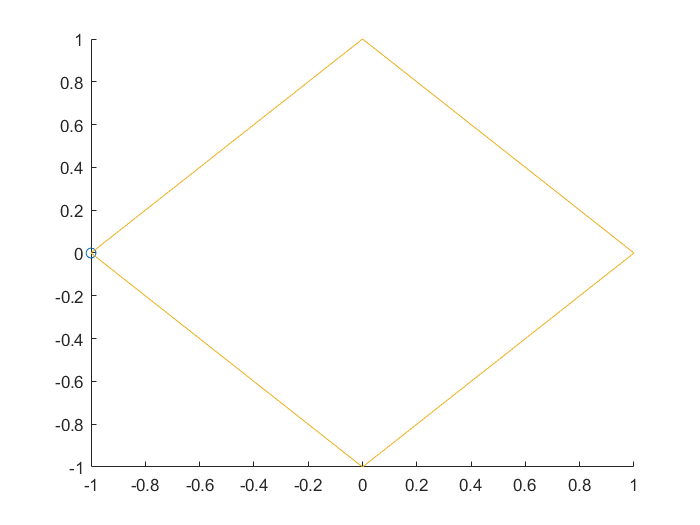

tiempo=[1:1.5:13];
t1= normalize(tiempo,"range",[pi,5*pi]);
x1= cos(t1);
y1= sin(t1);
comet(x1,y1)

**Figura 2: **

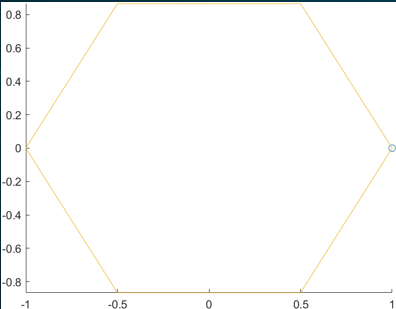

Ahora bien, antes de continuar con la parametrización de esta trayectoria, analicemos de igual forma que el incremento de ángulo del vector de tiempo esta relacionado con la medida de los ángulos internos de la figura. Por ejemplo, en la figura 1, el incremento que deseamos alcanzar era de pi/2. Para esta segunda figura, al tratarse de un hexagono, deseamos que el incremento en el vector de tiempo sea de 60°, es decir, pi/3. Jugando un poco con el vector de tiempo anterior y su normalización, especificametne reduciendo el valor del delta de tiempo para el vector, logramos replicar la trayectoria: 

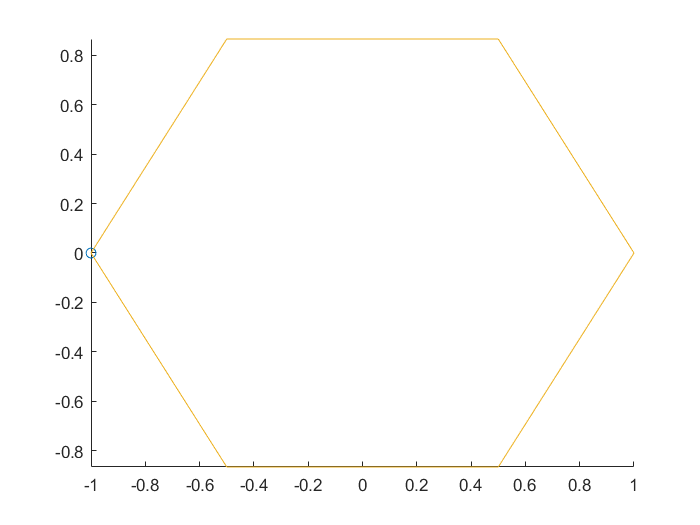

tiempo=[1:1:13];
t2= normalize(tiempo,"range",[pi,5*pi]);
x2= cos(t2);
y2= sin(t2);
comet(x2,y2)

**Figura 3:  **

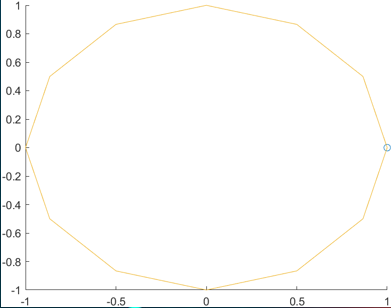

Comencemos por identificar la figura a replicar. En este caso, se trata de un dodecágno, es decir, de una figura de 12 lados. Para ajustar la trayectoria, partimos del los valores de la figura anterior y, en este caso, deseamos lograr un incremento de 30° (pi/6). Para lograr esto, reducimos a la mitad el incremento para el vector de tiempo: 

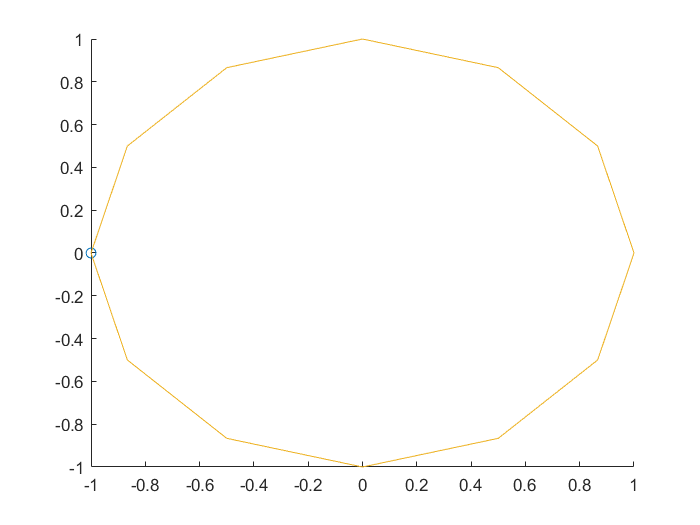

tiempo=[1:0.5:13];
t3= normalize(tiempo,"range",[pi,5*pi]);
x3= cos(t3);
y3= sin(t3);
comet(x3,y3)

**Figura 4:   **

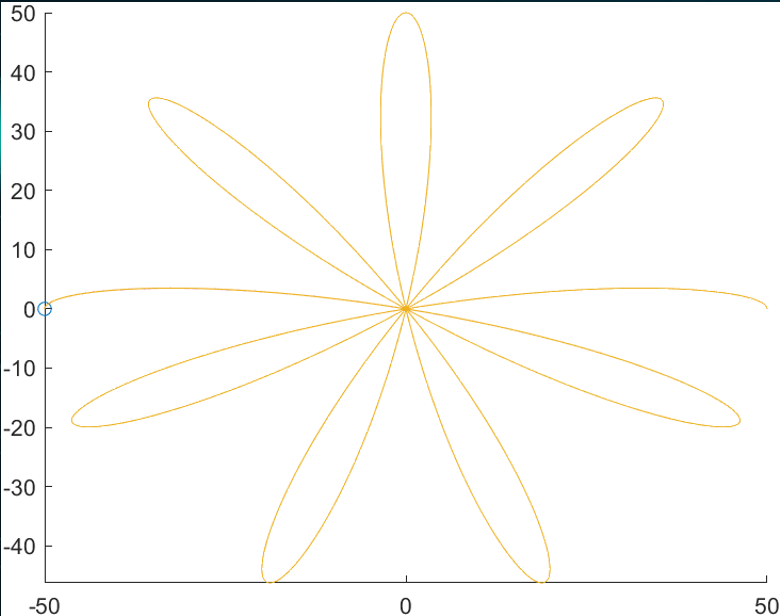

Para la generación de trayectoria similares a una flor, partimos del código proporcionado en la clase anterior, en dónde nos podemos dar cuenta que el valor multiplicado por theta (el argumento del coseno del parametro r) es el que define la cantidad de petalos de la flor. Para esta trayectoria, observamos que cuenta con 7 petalos completos y dos medios, por lo que se optó por variar este valor, encontrando que el valor multiplicado por theta debía ser 8. Por otro lado, todo eso se multiplicaría por 50 pues es la magnitud de la figura / trayectoria. 

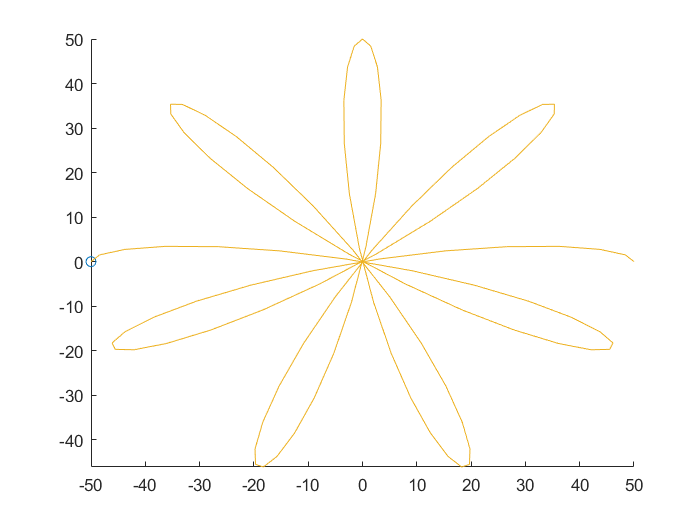

%Coordenadas polares
theta=0:pi/100:pi;
%Definimos el parámetro r como una función respecto a theta
r=50*cos(8*theta);
%Trasformamos las coordenas polares a cartesianas
x4= r.*cos(theta);
y4=r.*sin(theta);

comet(x4,y4)

**Figura 5: **

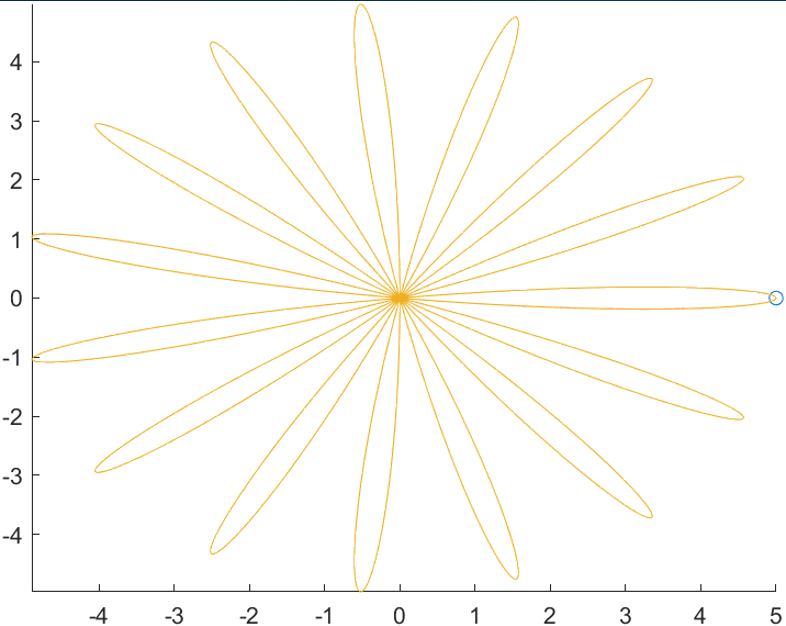

Para replicar esta trayectoria, partimos de uno de los códigos ejemplificados anteriormente. En este caso, multiplicamos por 15 al vector de tiempo dentro del argumento de coseno tanto para *x *como para *y, *esto debido a que la figura es una flor con 15 petalos. Además de esto, multiplicamos a la función por 5 ya que esta es su amplitud: 

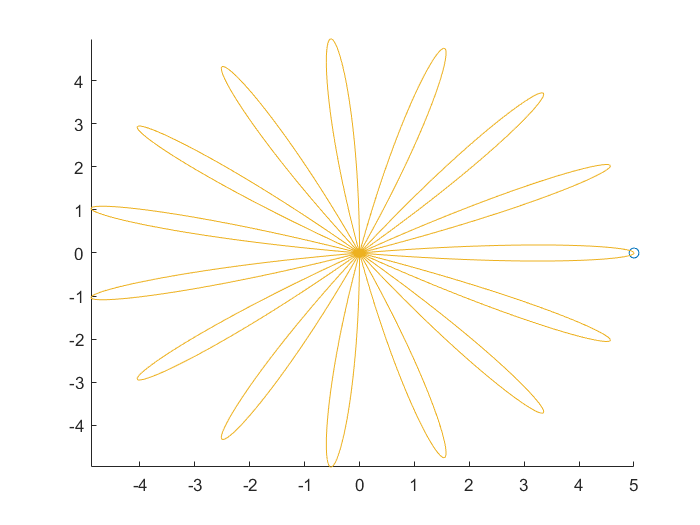

tiempo=[0:0.001:10];

t5= normalize(tiempo,"range",[0,pi]);

x5= 5*cos(15*t5).*cos(t5);
y5=5*cos(15*t5).*sin(t5);

comet(x5,y5)

**Figura 6: **

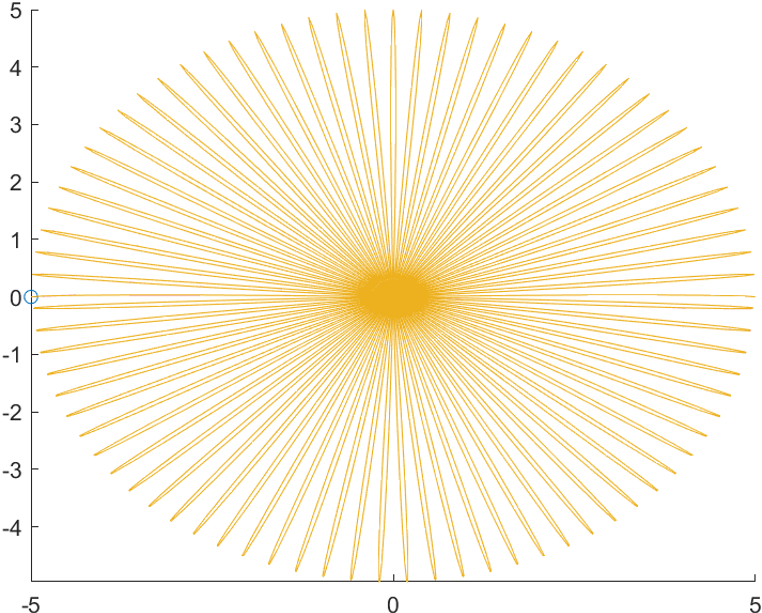

Para esta trayectoria, partimos del código de la figura anterior, modificandolo en función de la cantidad de pétalos de la trayectoria. Para este caso, la flor cuenta con aproximadamente 80 petalos: 

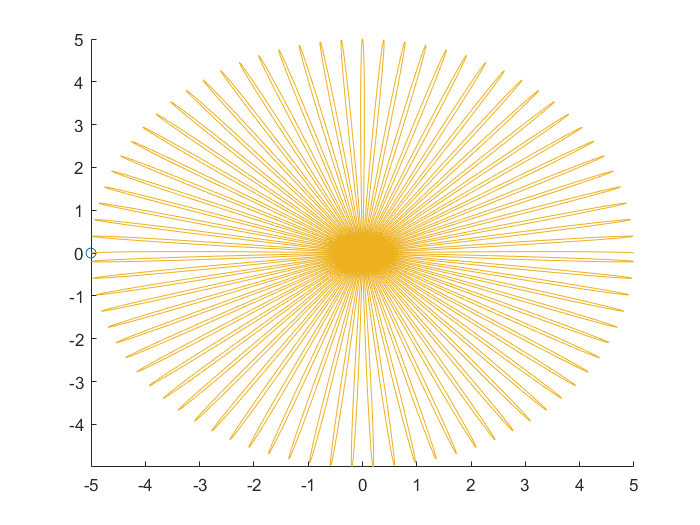

tiempo=[0:0.001:10];

t6= normalize(tiempo,"range",[0,pi]);

x6= 5*cos(80*t6).*cos(t6);
y6=5*cos(80*t6).*sin(t6);

comet(x6,y6)